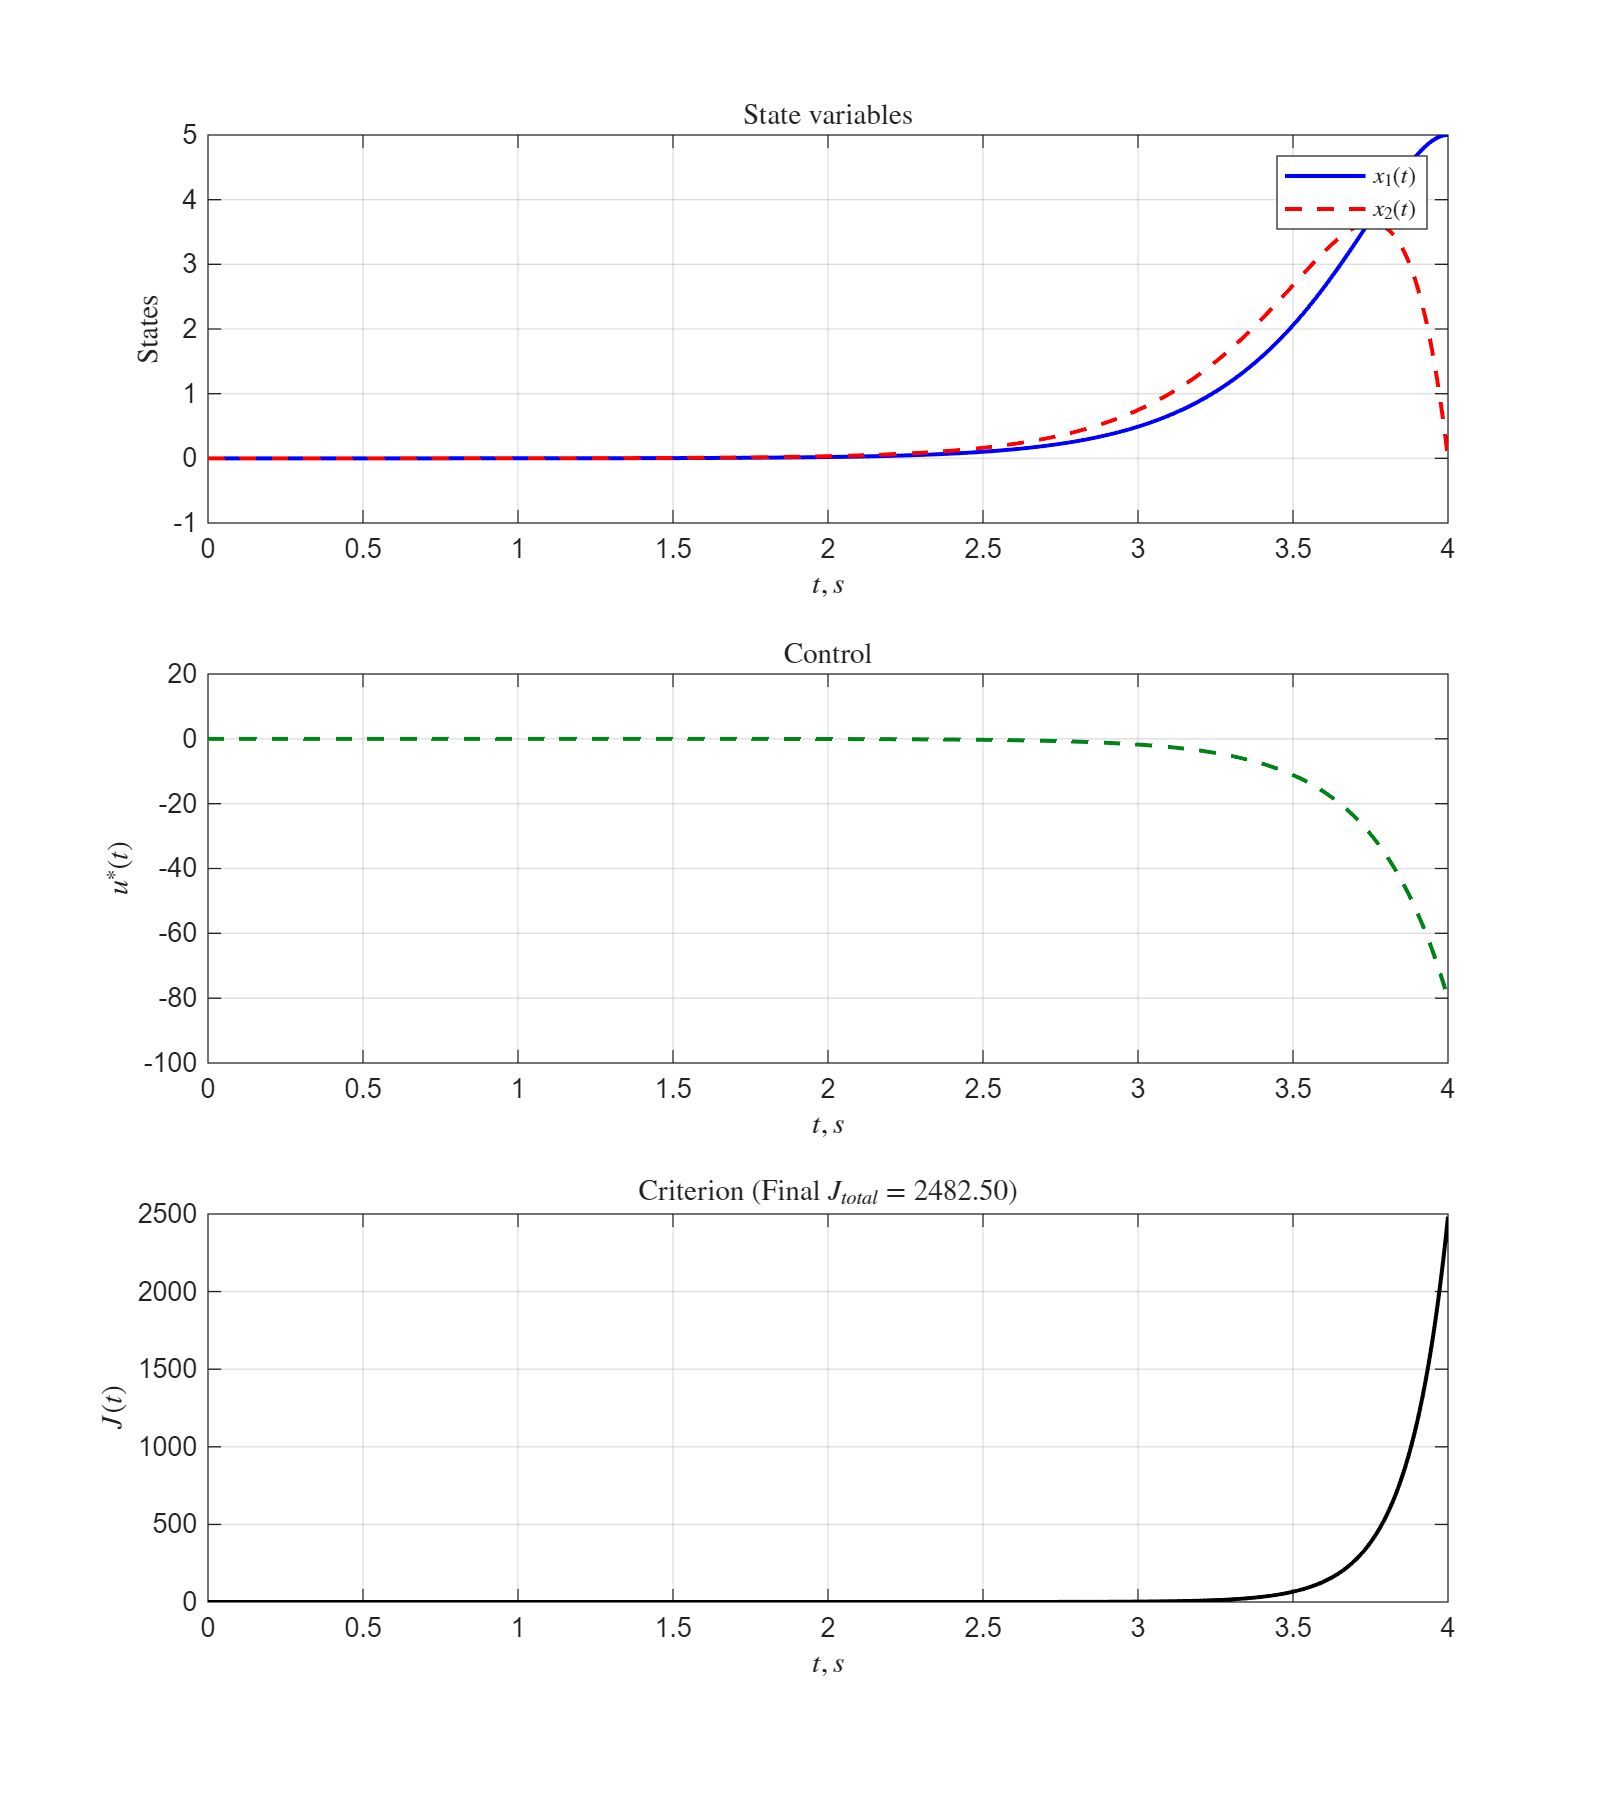

simtime = 4;
u_coeff = 1;
out = sim("lab1.slx", simtime);
t = out.y.Time;
x1 = out.y.Data(:, 1);
x2 = out.y.Data(:, 2);
u = out.u.Data;

integrand = x1.^2 + 5.*x1.*x2 + 7.*x2.^2 + 3.*u.^2;
J_cumulative = cumtrapz(t, integrand);
J_total = J_cumulative(end);

figure;
set(gcf, 'Position', [100, 100, 800, 900]); 

subplot(3,1,1);
plot(t, x1, 'b', 'LineWidth', 1.5); hold on;
plot(t, x2, 'r--', 'LineWidth', 1.5);
xlabel("$t, s$", Interpreter="latex");
ylabel("States", Interpreter="latex");
legend('\(x_1(t)\)', '\(x_2(t)\)', Interpreter="latex"); 
title("State variables", Interpreter="latex");
grid on;

subplot(3,1,2);
plot(t, u, 'Color', '#00841a', 'LineStyle', '--', 'LineWidth', 1.5);
xlabel("$t, s$", Interpreter="latex");
ylabel("\(u^*(t)\)", Interpreter="latex");
title("Control", Interpreter="latex");
grid on;

subplot(3,1,3);
plot(t, J_cumulative, 'k', 'LineWidth', 1.5);
xlabel("$t, s$", Interpreter="latex");
ylabel("\(J(t)\)", Interpreter="latex");
title(sprintf("Criterion (Final \\(J_{total} = %.2f\\))", J_total), Interpreter="latex");
grid on;

folder = "C:/Users/Nickolay/Desktop/ITMO-courses/7_term/Optimal_control_theory/lab2/tex/images/";
exportgraphics(gcf, folder + "lab1_plots.png", 'Resolution', 600);

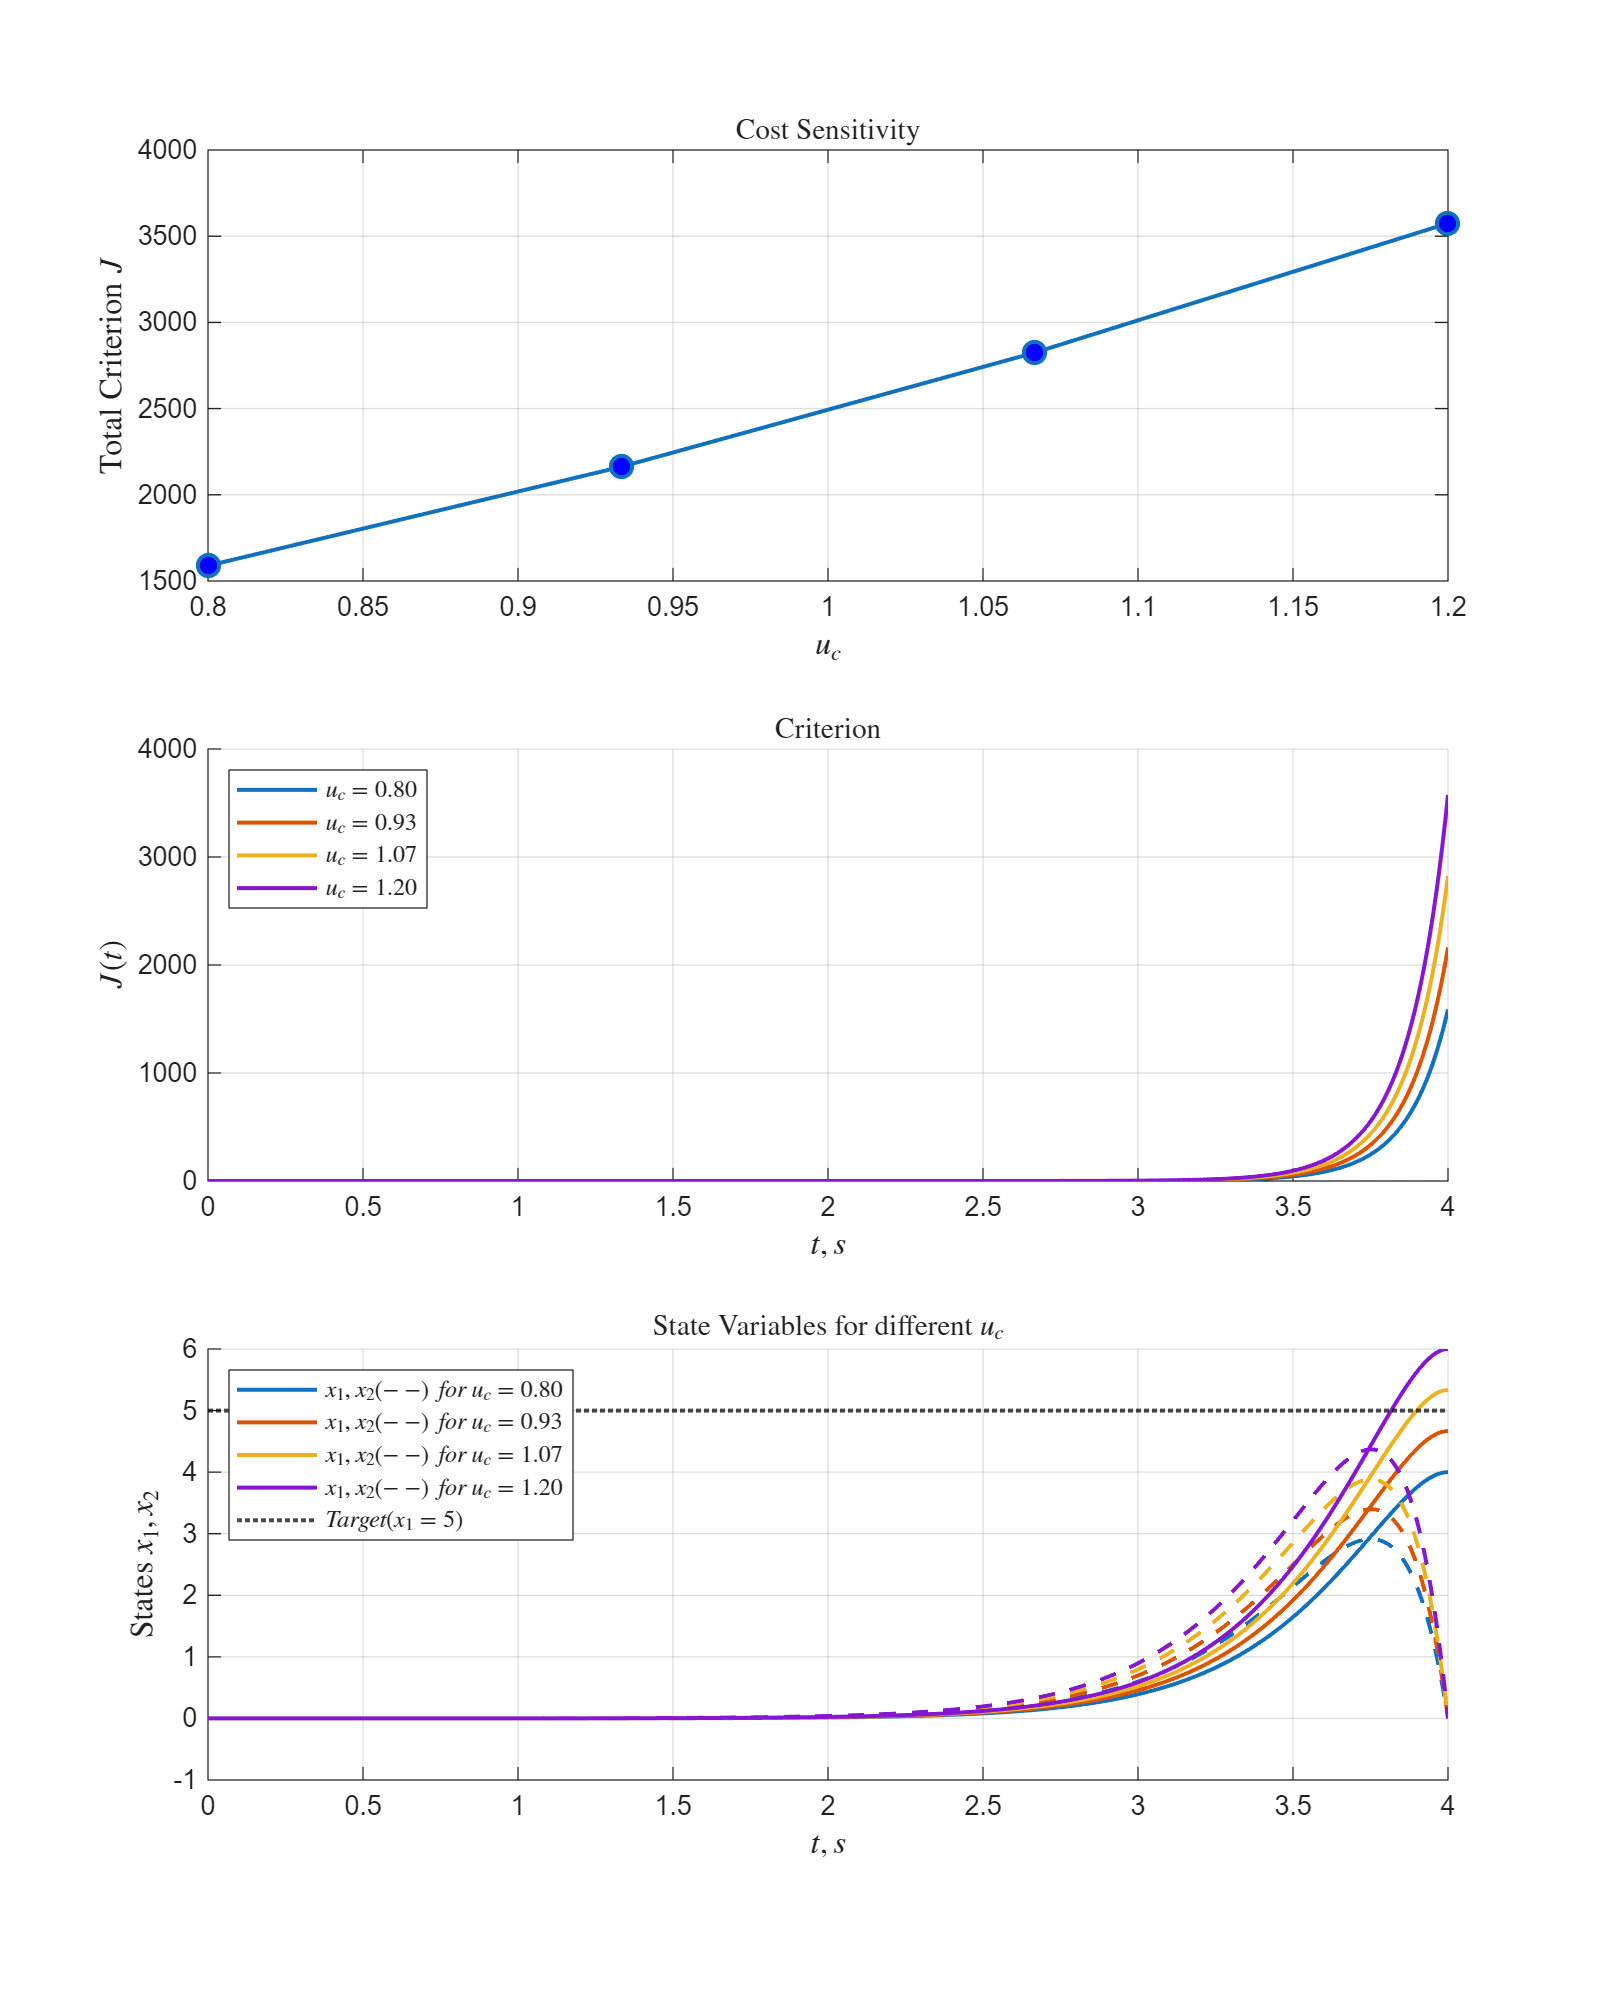

amount = 4;
factors = linspace(0.8, 1.2, amount); 

J_values = zeros(1, amount);
x1_final = zeros(1, amount);

J_cumulative_cell = cell(1, amount);
x1_cell = cell(1, amount);
x2_cell = cell(1, amount);

for i = 1:length(factors)
    u_coeff = factors(i);
    
    out = sim("lab1.slx", simtime);
    
    t = out.y.Time;
    x1 = out.y.Data(:, 1);
    x2 = out.y.Data(:, 2);
    u = out.u.Data;
    
    integrand = x1.^2 + 5.*x1.*x2 + 7.*x2.^2 + 3.*u.^2;
    
    J_cumulative = cumtrapz(t, integrand);
    J_total = J_cumulative(end);
    
    J_values(i) = J_total;
    x1_final(i) = x1(end);
    
    J_cumulative_cell{i} = J_cumulative;
    x1_cell{i} = x1;
    x2_cell{i} = x2;
end

figure('Name', 'Sensitivity to u deviation', 'Color', 'w');

set(gcf, 'Position', [100, 100, 800, 1000]); 

% --- Plot 1: Total Criterion vs Deviation Factor ---
subplot(3,1,1);
plot(factors, J_values, '-o', 'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel("\(u_{c}\)", Interpreter="latex", FontSize=12);
ylabel("Total Criterion \(J\)", Interpreter="latex", FontSize=12);
title("Cost Sensitivity", Interpreter="latex");
grid on;

% --- Plot 2: Cumulative Criterion over Time ---
subplot(3,1,2);
hold on;
colors = lines(length(factors)); 
for i = 1:length(factors)
    plot(t, J_cumulative_cell{i}, 'Color', colors(i,:), 'LineWidth', 1.5);
end
xlabel("\(t, s\)", Interpreter="latex", FontSize=12);
ylabel("\(J(t)\)", Interpreter="latex", FontSize=12);
title("Criterion", Interpreter="latex");
legendStrings = arrayfun(@(x) sprintf('$u_{c} = %.2f$', x), factors, 'UniformOutput', false);
legend(legendStrings, Interpreter="latex", Location="northwest", FontSize=9);
grid on;
hold off;

% --- Plot 3: State Variables over Time ---
subplot(3,1,3);
hold on;
colors = lines(length(factors)); 
for i = 1:length(factors)

    plot(t, x1_cell{i}, 'Color', colors(i,:), 'LineWidth', 1.5, 'DisplayName', sprintf('$x_1,~ x_2(--)~ for~ u_c = %.2f$', factors(i)));

    plot(t, x2_cell{i}, '--', 'Color', colors(i,:), 'LineWidth', 1.5, 'HandleVisibility', 'off'); 
end
xlabel("\(t, s\)", Interpreter="latex", FontSize=12);
ylabel("States \(x_1, x_2\)", Interpreter="latex", FontSize=12);
title("State Variables for different \(u_{c}\)", Interpreter="latex");

yline(5, 'k:', 'DisplayName', '$Target (x_1=5)$', 'LineWidth', 1.5, Interpreter="latex");
legend('Location', 'northwest', Interpreter="latex", FontSize=9);
grid on;
hold off;

exportgraphics(gcf, folder + "lab1_plots2.png", 'Resolution', 600);